# Exercise 3.2 - Echo II

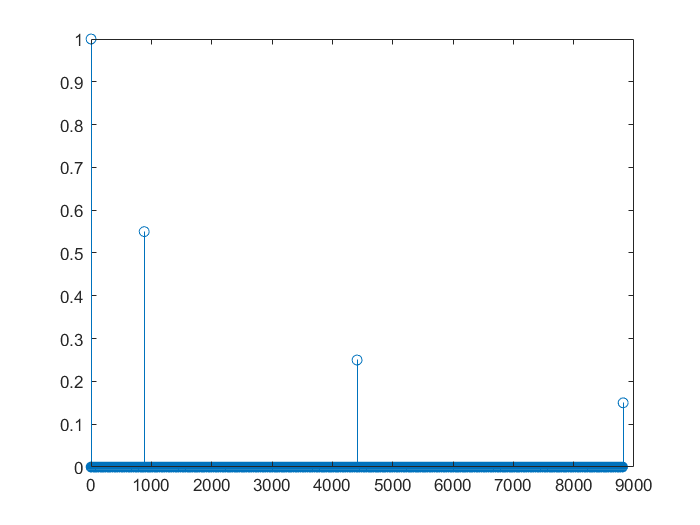

% Import audio file
[kick, fs] = audioread('audio\kick.mp3');
%sound(kick, fs)

% Echo setup
eco1 = 20e-3;
eco2 = 100e-3;
eco3 = 200e-3;
numSamples1 = fs * eco1;
numSamples2 = fs * eco2;
numSamples3 = fs * eco3;
b = zeros(1, numSamples3 + 1);
b(1) = 1;
b(numSamples1 + 1) = 0.55;
b(numSamples2 + 1) = 0.25;
b(numSamples3 + 1) = 0.15;

% Apply filter and play output signal
y = filter(b, 1, kick);
sound(y, fs)

% Export resulting audio fragment in WAV format
audiowrite('audio\output3_2.wav', 0.5 * y, fs);

% Plot the b coefficients vector
n = 0 : numSamples3;
stem(n, b);